c1 = 0.5176;                    % value given 
c2 = 116;                       % value given
c3 = 0.4;                       % value given
c4 = 5;                         % value given
c5 = 21;                        % value given
c6 = 0.0068;                    % value given
R = 9;                          % raduis 
wind = 18;                      % wind speed 
r=1.2;                          % air density
A=pi*R^2;                       % turbine sweep area
swp = 0.5*r*A;                  % sweep 

for B = 0:1:inf                 %loop for beta 
    Cp_opt = 0;        
    Psave=[];
    Vrotorsave=[];

    for V_rotor = 1:1:inf      % Loop for rotor speed values
        lambda = (V_rotor * 2 * pi * R) / (60 * wind);
        T = 1 ./ (lambda + 0.08 * B) - (0.035 / (B^3 + 1));    %Power Coefficient
        Cp = c1 * (c2 * T - c3 * B - c4) * exp(-c5 * T) + c6 * lambda;% Replace with your actual Cp calculation formula
        P= swp*(Cp*wind.^3);

        Psave=[Psave P];
        Vrotorsave=[Vrotorsave V_rotor];

         if Cp > Cp_opt
            V_rotor_opt = V_rotor;
            Cp_opt = Cp;
            
        else
                 % Cp begins to decrease then need to find the optimal
                 % Cp_opt,if not exit form loop 
            break;
        end
    end
    
    if V_rotor_opt <= 90 && Cp_opt < 100e3
        % If V_rotor_opt <= 90rpm and p_opt < 100e3, break out of the loop
        break;
    end
end

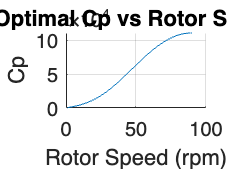

% Plot the graph
figure;
hold on; 
plot(Vrotorsave, Psave);
xlabel('Rotor Speed (rpm)');
ylabel('Cp');
title('Optimal Cp vs Rotor Speed');
grid on;